# Trabajo práctico: Etapas típicas en procesamiento digital de señales

## Generación de una señal con cierta frecuencia de muestreo

1. Escriba un programa en MATLAB que grafique una función senoidal con las siguientes especificaciones:

- Frecuencia: 100 Hz.

- Frecuecia de muestreo: 1000 Hz.

- Tiempo inicio: 0 s.

- Tiempo final: 1 s.

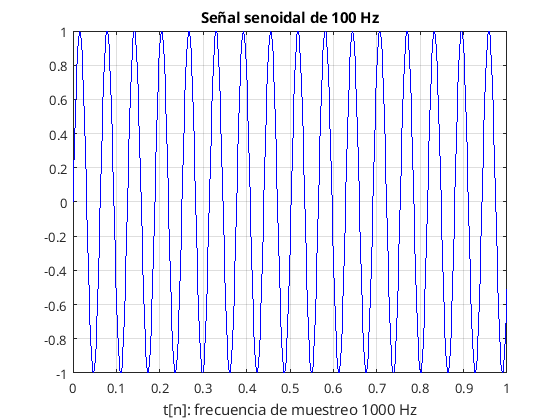

fN = 100; fS = 1000; t0 = 0; tF = 1;

TS = 1 / fS;
t = t0:TS:tF;

signal = sin(fN*t);

figure(1)
plot(t, signal, '-b');
grid on;
title("Señal senoidal de 100 Hz");
xlabel("t[n]: frecuencia de muestreo 1000 Hz");

## Agregar ruido a una señal

2. Escriba un programa en MATLAB que permita agregar a la señal del Ejercicio 1 cierta cantidad de ruido blanco gaussiano.

    1. Obtenga la varianza del ruido a partir de la relación:


$$SNR = 10 \log \frac{\sigma^{2}_{signal}}{\sigma^{2}_{noise}}$$


    2. Utilice la función `randn() `para simular el ruido (`help randn`).

    3. El prototipo de la función debe ser `signal_n = my_awgn(signal, snr)`. Los datos de entrada son el vector `signal` y el escalar `snr`.

    4. La varianza de signal se puede calcular con la función `var` (`help var`).

    5. Compare las salidas de las funciones `my_awgn` y `awgn` (`help awgn`).

figure(2)
plot(t, my_awgn(signal, 15), '-r')